clear all; close all

First, we verify just with MATLAB's matrix multiplication.

theta=30

theta = 30

R=[cosd(theta), -sind(theta);
    sind(theta), cosd(theta)]

R =     0.8660   -0.5000
    0.5000    0.8660


v=[-1;
    -2]

v =     -1
    -2


R*v

ans =     0.1340
   -2.2321


Now, we check from the definition, doing a linear combination of the transformed basis vectors.

ri=[cosd(theta);sind(theta)]

ri =     0.8660
    0.5000


rj=[-sind(theta); cosd(theta)]

rj =    -0.5000
    0.8660



v(1)*ri+v(2)*rj

ans =     0.1340
   -2.2321


Load the smiley face with the rotated smile

load +linalg/separate_face_points.mat
face_points

face_points =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0

smile_points

smile_points =     0.2500    0.2591    0.2681    0.2770    0.2857    0.2943    0.3028    0.3112    0.3194    0.3274    0.3354    0.3431    0.3507    0.3582    0.3655    0.3726    0.3796    0.3864    0.3930    0.3995    0.4057    0.4118    0.4177    0.4235    0.4290    0.4343    0.4395    0.4444    0.4492    0.4537    0.4581    0.4622    0.4661    0.4698    0.4734    0.4767    0.4797    0.4826    0.4853    0.4877    0.4899    0.4919    0.4937    0.4953    0.4966    0.4977    0.4986    0.4993    0.4997    0.5000
    0.4330    0.4276    0.4221    0.4163    0.4103    0.4042    0.3979    0.3914    0.3847    0.3779    0.3709    0.3637    0.3563    0.3488    0.3412    0.3334    0.3254    0.3173    0.3091    0.3007    0.2922    0.2835    0.2748    0.2659    0.2568    0.2477    0.2385    0.2291    0.2197    0.2101    0.2005    0.1907    0.1809    0.1710    0.1610    0.1510    0.1409    0.1307    0.1204    0.1102    0.0998    0.0894    0.0790    0.0685    0.0580    0.0475    0.0370    0.0264    

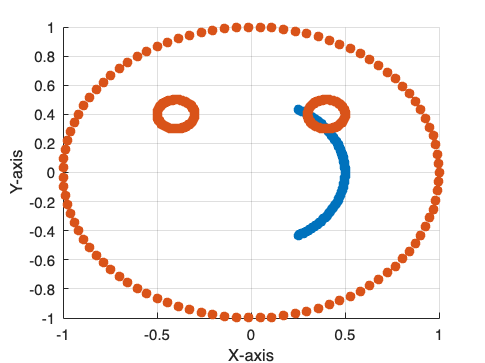

linalg.simple_plot_cloud(smile_points,face_points);

Re-write each vector (column) "v" in smile_points as the rotated vector Rv

theta=-90

theta = -90

R=[cosd(theta), -sind(theta);
    sind(theta), cosd(theta)]

R =      0     1
    -1     0


for i=1:size(smile_points,2)
    smile_points(:,i)=R*smile_points(:,i);
end
smile_points

smile_points =     0.4330    0.4276    0.4221    0.4163    0.4103    0.4042    0.3979    0.3914    0.3847    0.3779    0.3709    0.3637    0.3563    0.3488    0.3412    0.3334    0.3254    0.3173    0.3091    0.3007    0.2922    0.2835    0.2748    0.2659    0.2568    0.2477    0.2385    0.2291    0.2197    0.2101    0.2005    0.1907    0.1809    0.1710    0.1610    0.1510    0.1409    0.1307    0.1204    0.1102    0.0998    0.0894    0.0790    0.0685    0.0580    0.0475    0.0370    0.0264    0.0159    0.0053
   -0.2500   -0.2591   -0.2681   -0.2770   -0.2857   -0.2943   -0.3028   -0.3112   -0.3194   -0.3274   -0.3354   -0.3431   -0.3507   -0.3582   -0.3655   -0.3726   -0.3796   -0.3864   -0.3930   -0.3995   -0.4057   -0.4118   -0.4177   -0.4235   -0.4290   -0.4343   -0.4395   -0.4444   -0.4492   -0.4537   -0.4581   -0.4622   -0.4661   -0.4698   -0.4734   -0.4767   -0.4797   -0.4826   -0.4853   -0.4877   -0.4899   -0.4919   -0.4937   -0.4953   -0.4966   -0.4977   -0.4986   -0.4993   -

Check that the rotation worked

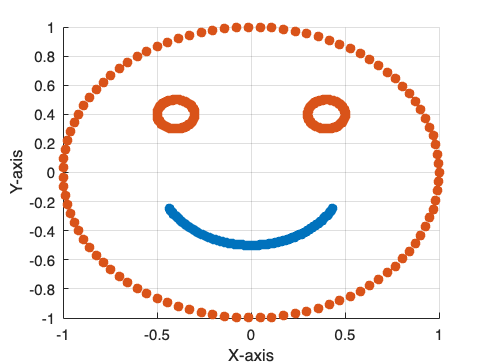

linalg.simple_plot_cloud(smile_points,face_points);

**Extra Practice: Matrix Multiplication**

As you'll see in the next section (and in the discussion if you're taking this class online), you can think about matrix multiplication as doing the effects of multiple transformations in sequence. The following sections provide more practice carrying out this phenomenon.

First, rather than just transforming the smile, let's transform the whole face by combining the matrices face_points and smile_points. 

The notation [face_points,smile_points] combines these two matrices by listing the columns of smile_points after the columns of face_points, hence the use of "," to separate the matrices.

full_face=[face_points,smile_points]

full_face =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0

We then make a copy of full_face so that we can manipulate the matrix without changing the original data.

test_face=full_face

First stretch the smiley.

S = [1 0; 0 2];
for i=1:size(test_face,2)
    test_face(:,i)=S*test_face(:,i);
end

linalg.simple_plot_cloud(test_face)

Then rotate the stretched vectors. Note that we're still doing this transformation on full_face, which has just been stretched

R = [cosd(60) -sind(60); sind(60) cosd(60)];
for i=1:length(face_points)
    test_face(:,i)=R*test_face(:,i);
end
linalg.plot_img_points(test_face)

Now check that the product R*S gives you the same result after application on full_face. 

test_face_2=full_face

S = [1 0; 0 2]
R = [cosd(60) -sind(60); sind(60) cosd(60)];
RS = R*S
for i=1:length(face_points)
    test_face_2(:,i)=RS*test_face_2(:,i);
end
linalg.plot_img_points(test_face_2)

**Extra Practice: Effecient Data Transformation with Matrix Multiplication**

As you see at the end of the chapter, the computation of matrix multiplication actually lets us skip use of the "for loop" to transform the data. 

Since matrix multiplication is the same as matrxi-vector multiplication on the individual columns of the right matrix in the multiplication, we can transform the data entirely by treating it as a matrix in its own right.

The only difference is that the matrix full_face is being treated as data, not as a transformation, and we care to plot the resulting vectors. The matrices S, R, and F (new, below) are the transformation matrices, where we're treating them as instructions for stretching and compressing and rotating the data matrix full_face. 

Keeping in mind the two different ways we're interpreting and using matrices in this example is important.

test_face=full_face

First we try three transformations individually and check the result after each one. 

As before, we stretch and rotate, but then we flip across the vertical axis (by switching the x-component to be negative) in the matrix F.

S = [1 0; 0 2]

S =      1     0
     0     2


R = [cosd(60) -sind(60); sind(60) cosd(60)]

R =     0.5000   -0.8660
    0.8660    0.5000


F = [-1 0; 0 1]

F =     -1     0
     0     1



test_face=full_face

test_face =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0

Now do each transformation individually and check the progressive result.

test_face=S*test_face

test_face =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.1268    0.2532    0.3785    0.5023    0.6241    0.7433    0.8596    0.9724    1.0813    1.1858    1.2856    1.3802    1.4692    1.5523    1.6292    1.6995    1.7629    1.8193    1.8683    1.9098    1.9436    1.9696    1.9877    1.9977    1.9997    1.9937    1.9796    1.9576    1.9277    1.8900    1.8447    1.7920    1.7321    1.6651    1.5915    1.5115    1.4254    1.3335    1.2363    1.1341    1.0274    0.9165    0.8019    0.6840    0.5635    0.4406    0.3160    0.1

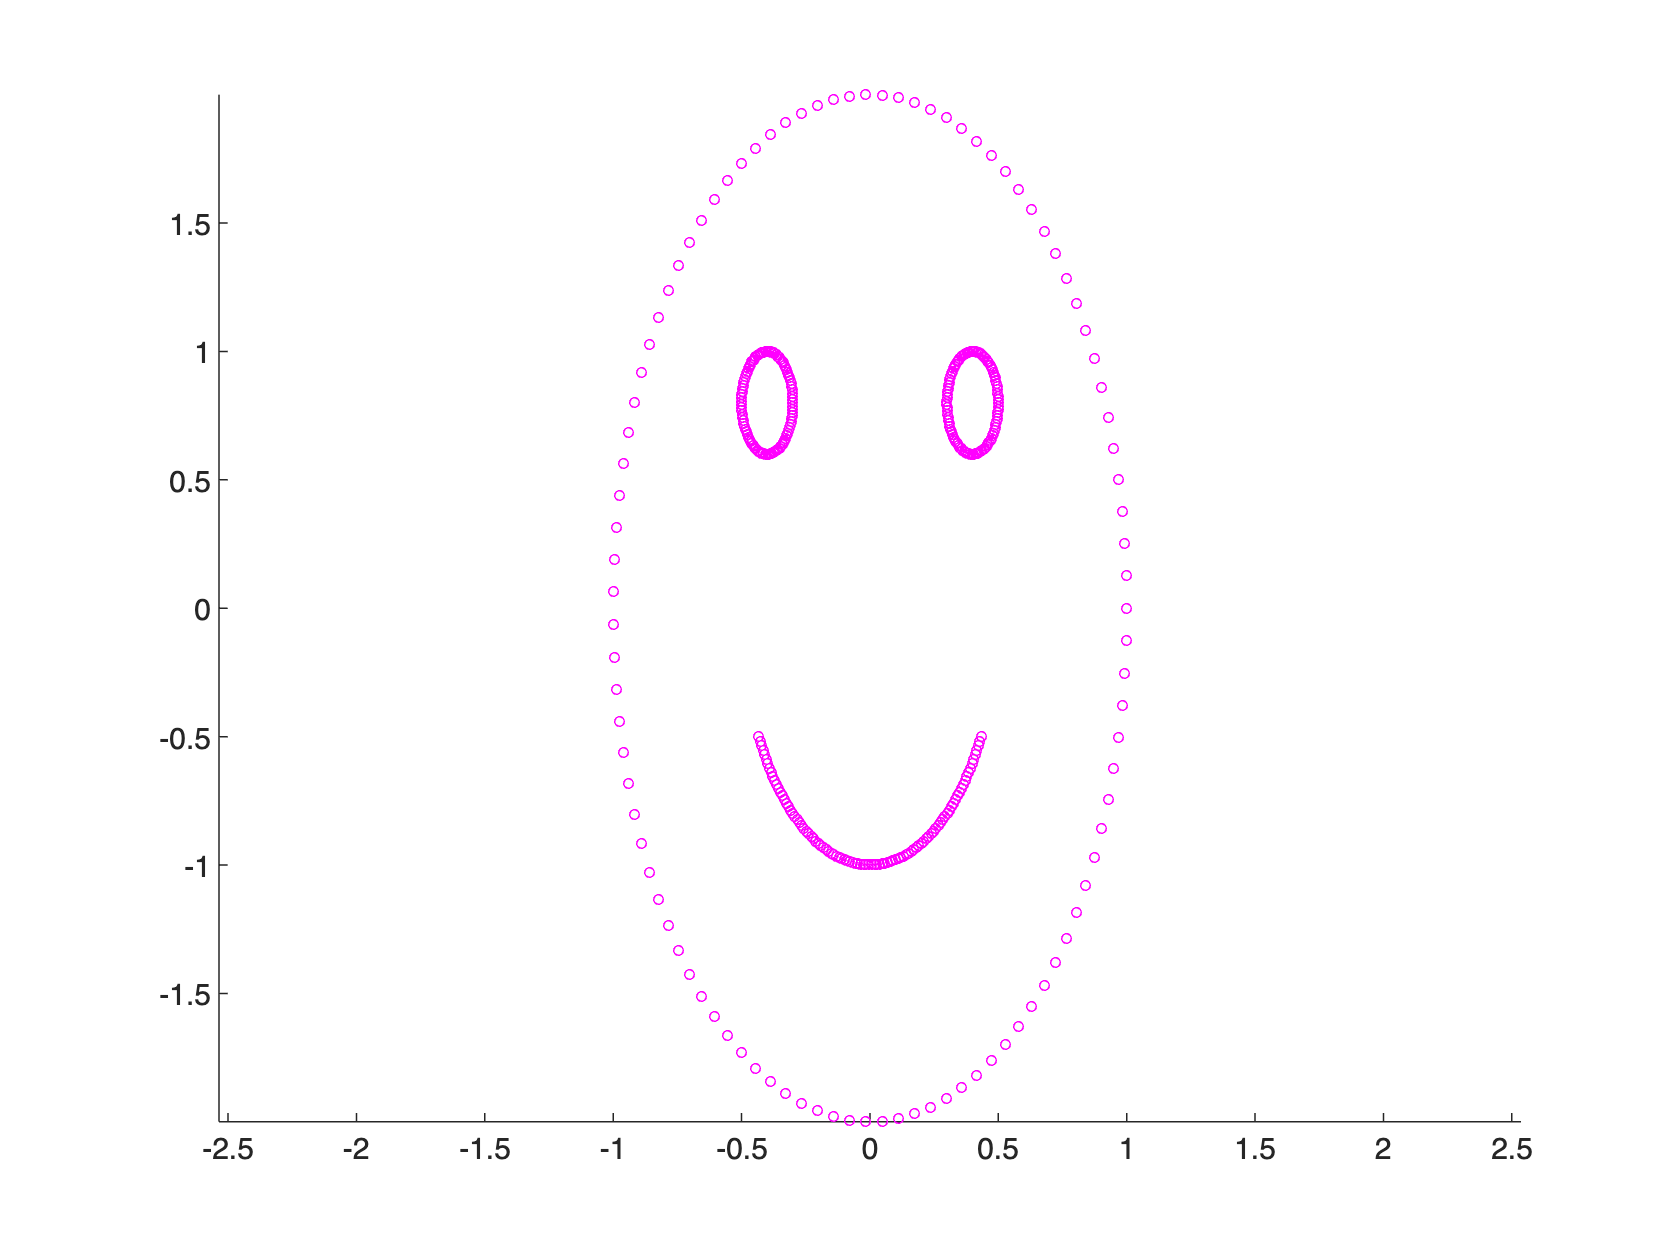

linalg.plot_img_points(test_face)

Remember that with each matrix multiplcation we're re-defining test_face, so in each new line we are performuing **further transformations** on the already transformed face.

test_face=R*test_face

test_face =     0.5000    0.3891    0.2767    0.1632    0.0490   -0.0654   -0.1796   -0.2930   -0.4052   -0.5158   -0.6243   -0.7303   -0.8334   -0.9331   -1.0290   -1.1209   -1.2082   -1.2906   -1.3678   -1.4395   -1.5055   -1.5653   -1.6189   -1.6660   -1.7063   -1.7398   -1.7662   -1.7856   -1.7977   -1.8027   -1.8003   -1.7907   -1.7739   -1.7500   -1.7190   -1.6811   -1.6364   -1.5852   -1.5275   -1.4637   -1.3940   -1.3187   -1.2381   -1.1525   -1.0622   -0.9677   -0.8693   -0.7674   -0.6624   -0.5547
    0.8660    0.9277    0.9857    1.0396    1.0894    1.1348    1.1757    1.2118    1.2430    1.2692    1.2903    1.3062    1.3169    1.3222    1.3222    1.3169    1.3063    1.2905    1.2694    1.2432    1.2120    1.1760    1.1352    1.0898    1.0401    0.9861    0.9282    0.8666    0.8014    0.7331    0.6618    0.5878    0.5114    0.4330    0.3529    0.2713    0.1886    0.1052    0.0214   -0.0626   -0.1463   -0.2294   -0.3115   -0.3924   -0.4718   -0.5492   -0.6244   -0.6971   -0.7

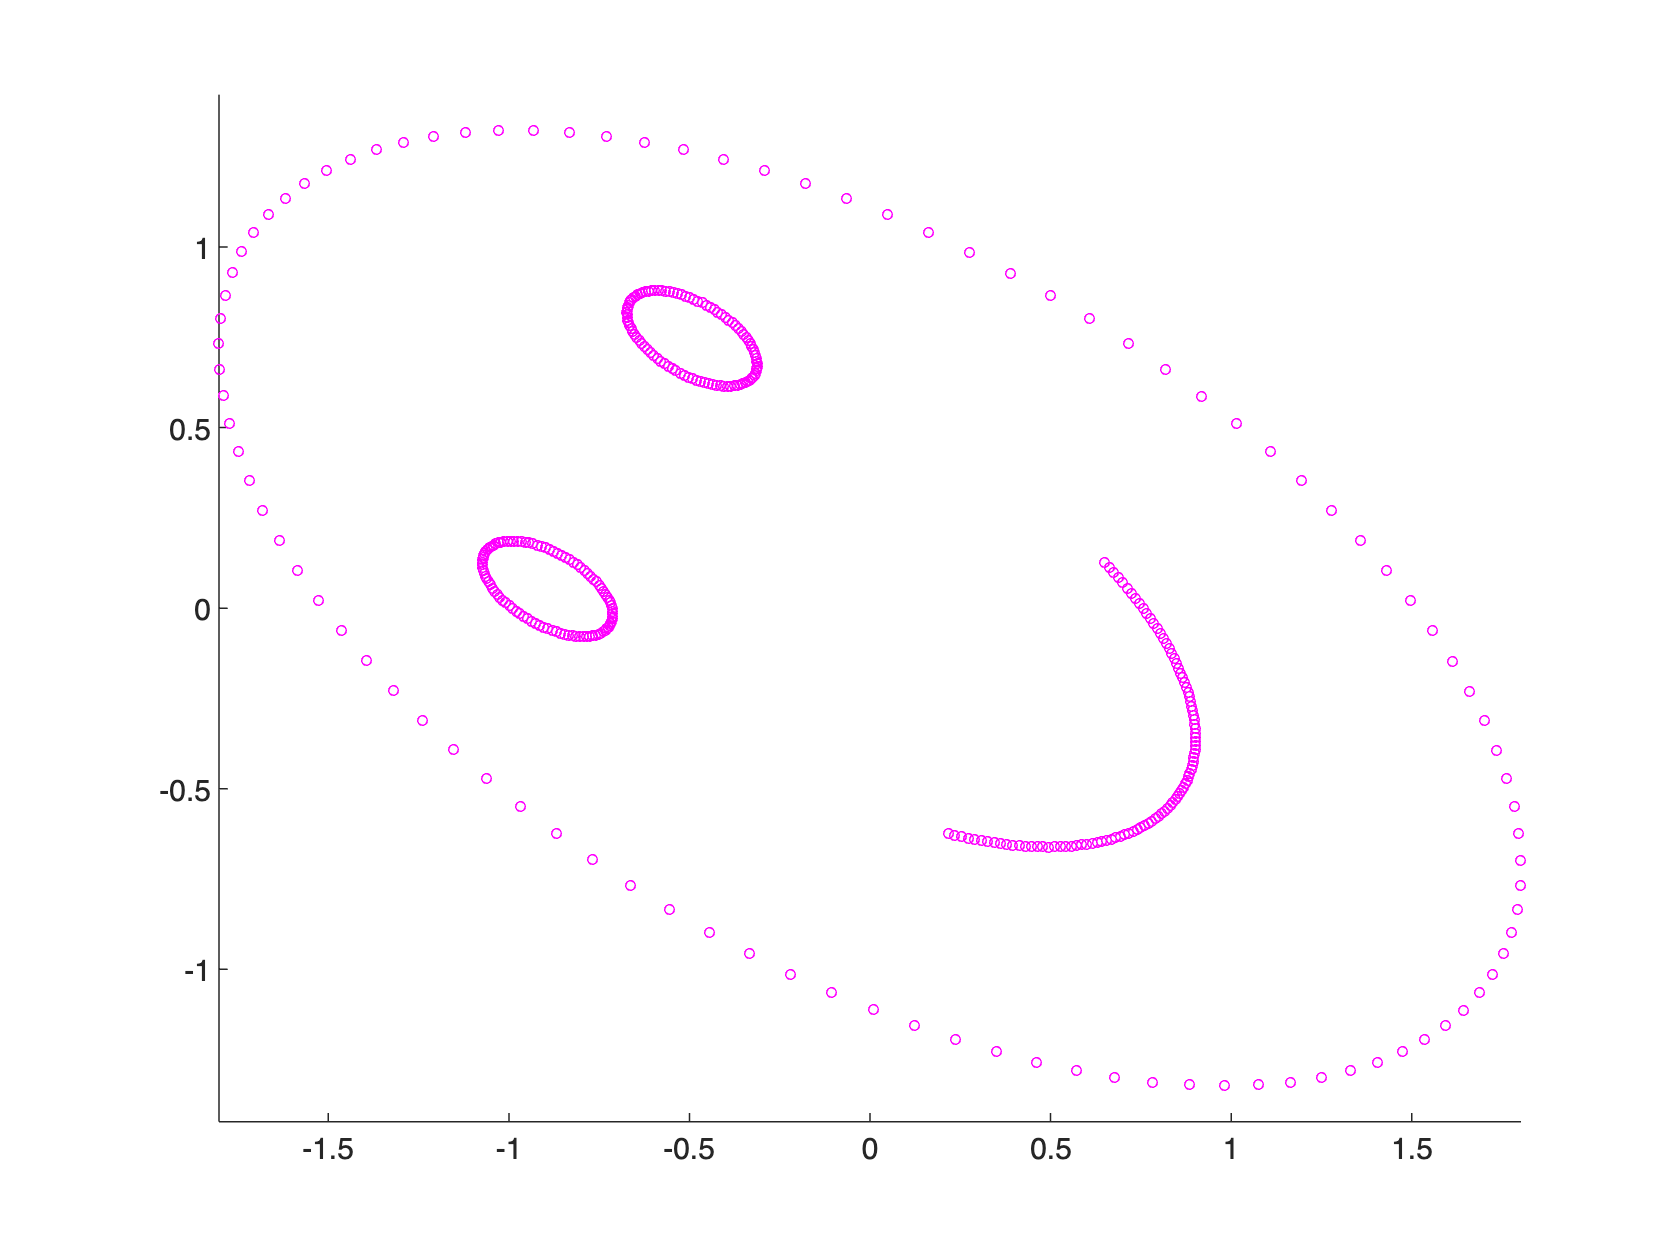

linalg.plot_img_points(test_face)


test_face=F*test_face

test_face =    -0.5000   -0.3891   -0.2767   -0.1632   -0.0490    0.0654    0.1796    0.2930    0.4052    0.5158    0.6243    0.7303    0.8334    0.9331    1.0290    1.1209    1.2082    1.2906    1.3678    1.4395    1.5055    1.5653    1.6189    1.6660    1.7063    1.7398    1.7662    1.7856    1.7977    1.8027    1.8003    1.7907    1.7739    1.7500    1.7190    1.6811    1.6364    1.5852    1.5275    1.4637    1.3940    1.3187    1.2381    1.1525    1.0622    0.9677    0.8693    0.7674    0.6624    0.5547
    0.8660    0.9277    0.9857    1.0396    1.0894    1.1348    1.1757    1.2118    1.2430    1.2692    1.2903    1.3062    1.3169    1.3222    1.3222    1.3169    1.3063    1.2905    1.2694    1.2432    1.2120    1.1760    1.1352    1.0898    1.0401    0.9861    0.9282    0.8666    0.8014    0.7331    0.6618    0.5878    0.5114    0.4330    0.3529    0.2713    0.1886    0.1052    0.0214   -0.0626   -0.1463   -0.2294   -0.3115   -0.3924   -0.4718   -0.5492   -0.6244   -0.6971   -0.7

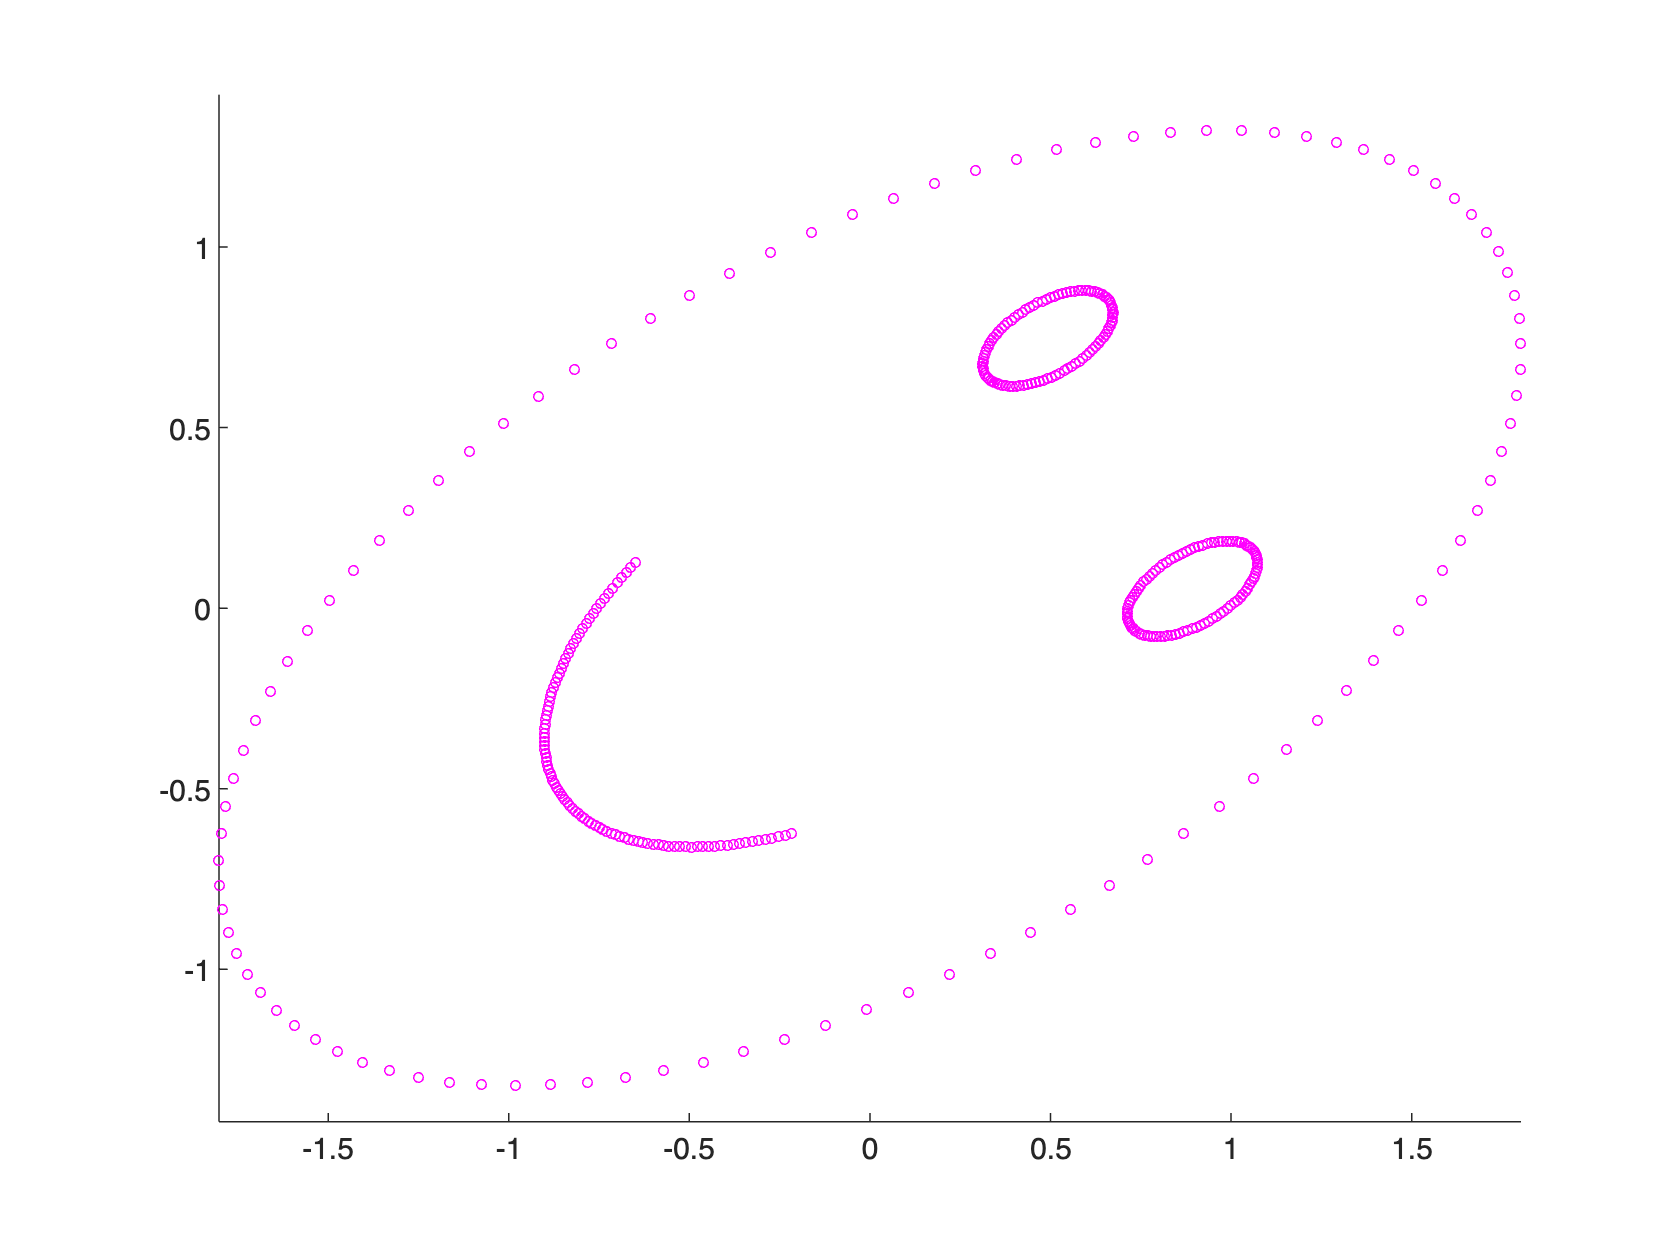

linalg.plot_img_points(test_face)

Now, we see if the product of the three transformations yeilds the same final result. 

test_face_2=full_face

test_face_2 =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0


R = [cosd(60) -sind(60); sind(60) cosd(60)]

R =     0.5000   -0.8660
    0.8660    0.5000


S = [1 0; 0 2]

S =      1     0
     0     2


F = [-1 0; 0 1]

F =     -1     0
     0     1


M = F*R*S

M =    -0.5000    1.7321
    0.8660    1.0000


for i=1:size(test_face_2,2)
    test_face_2(:,i) = M *test_face_2(:,i);
end
linalg.plot_img_points(test_face_2)

Now, we check if reversing the order of the transformation gives the same result. If so, this would mean that matrxi multiplication is **commutative**, just like how real number multiplication is the same no matter in what order you put the numbers.

test_face=full_face

test_face =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0

test_face_2=full_face

test_face_2 =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
         0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0

R = [cosd(60) -sind(60); sind(60) cosd(60)]

R =     0.5000   -0.8660
    0.8660    0.5000


S = [1 0; 0 2]

S =      1     0
     0     2


SR=S*R

SR =     0.5000   -0.8660
    1.7321    1.0000


RS=R*S

RS =     0.5000   -1.7321
    0.8660    1.0000


test_face=SR*test_face

test_face =     0.5000    0.4441    0.3863    0.3271    0.2665    0.2048    0.1423    0.0792    0.0159   -0.0476   -0.1108   -0.1736   -0.2358   -0.2969   -0.3569   -0.4154   -0.4723   -0.5272   -0.5801   -0.6306   -0.6785   -0.7237   -0.7660   -0.8053   -0.8413   -0.8738   -0.9029   -0.9284   -0.9501   -0.9679   -0.9819   -0.9920   -0.9980   -1.0000   -0.9980   -0.9920   -0.9819   -0.9679   -0.9501   -0.9284   -0.9029   -0.8738   -0.8413   -0.8053   -0.7660   -0.7237   -0.6785   -0.6306   -0.5801   -0.5272
    1.7321    1.7920    1.8447    1.8900    1.9277    1.9576    1.9796    1.9937    1.9997    1.9977    1.9877    1.9696    1.9436    1.9098    1.8683    1.8193    1.7629    1.6995    1.6292    1.5523    1.4692    1.3802    1.2856    1.1858    1.0813    0.9724    0.8596    0.7433    0.6241    0.5023    0.3785    0.2532    0.1268   -0.0000   -0.1268   -0.2532   -0.3785   -0.5023   -0.6241   -0.7433   -0.8596   -0.9724   -1.0813   -1.1858   -1.2856   -1.3802   -1.4692   -1.5523   -1.6

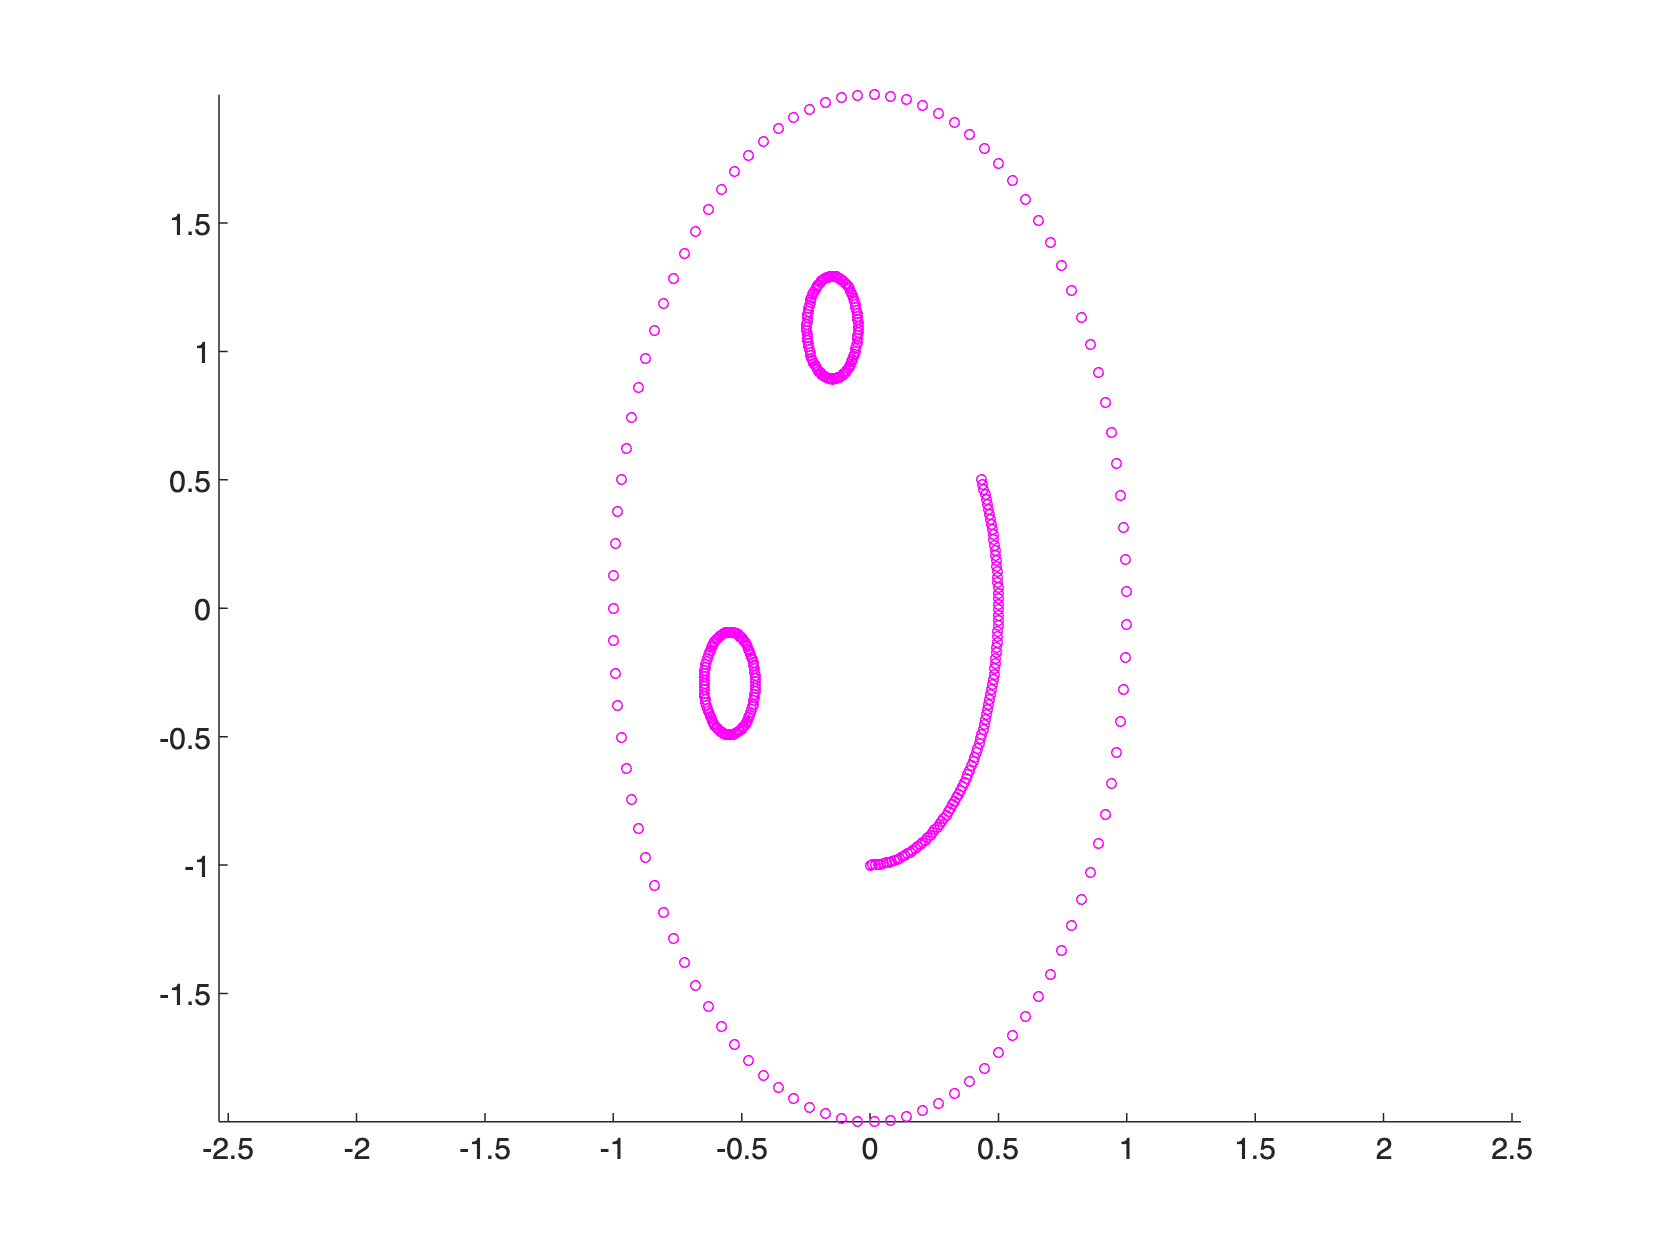

linalg.plot_img_points(test_face)


test_face_2=RS*test_face_2

test_face_2 =     0.5000    0.3891    0.2767    0.1632    0.0490   -0.0654   -0.1796   -0.2930   -0.4052   -0.5158   -0.6243   -0.7303   -0.8334   -0.9331   -1.0290   -1.1209   -1.2082   -1.2906   -1.3678   -1.4395   -1.5055   -1.5653   -1.6189   -1.6660   -1.7063   -1.7398   -1.7662   -1.7856   -1.7977   -1.8027   -1.8003   -1.7907   -1.7739   -1.7500   -1.7190   -1.6811   -1.6364   -1.5852   -1.5275   -1.4637   -1.3940   -1.3187   -1.2381   -1.1525   -1.0622   -0.9677   -0.8693   -0.7674   -0.6624   -0.5547
    0.8660    0.9277    0.9857    1.0396    1.0894    1.1348    1.1757    1.2118    1.2430    1.2692    1.2903    1.3062    1.3169    1.3222    1.3222    1.3169    1.3063    1.2905    1.2694    1.2432    1.2120    1.1760    1.1352    1.0898    1.0401    0.9861    0.9282    0.8666    0.8014    0.7331    0.6618    0.5878    0.5114    0.4330    0.3529    0.2713    0.1886    0.1052    0.0214   -0.0626   -0.1463   -0.2294   -0.3115   -0.3924   -0.4718   -0.5492   -0.6244   -0.6971   -0

linalg.plot_img_points(test_face_2)

These are different final results, so multiplying two matrices together possibly gives different transformations of data, meaning that **order matters** for matrix multiplication.